# Introduction to Simple Linear Regression

## Regression Model

Read data from an external file (SalaryData.csv),  The first column represents years in service while the second column represents annual salary. The data set can also be obtained from [https://www.kaggle.com/karthickveerakumar/salary-data-simple-linear-regression](https://www.kaggle.com/karthickveerakumar/salary-data-simple-linear-regression).

data=readtable('SalaryData.csv','ReadVariableNames',false);
data.Properties.VariableNames = {'YearsExperience','Salary'}

data = 30×2 table
    YearsExperience      Salary  
    _______________    __________

      1.1000e+00       3.9343e+04
      1.3000e+00       4.6205e+04
      1.5000e+00       3.7731e+04
      2.0000e+00       4.3525e+04
      2.2000e+00       3.9891e+04
      2.9000e+00       5.6642e+04
      3.0000e+00       6.0150e+04
      3.2000e+00       5.4445e+04
      3.2000e+00       6.4445e+04
      3.7000e+00       5.7189e+04
      3.9000e+00       6.3218e+04
      4.0000e+00       5.5794e+04
      4.0000e+00       5.6957e+04
      4.1000e+00       5.7081e+04
      4.5000e+00       6.1111e+04
      4.9000e+00       6.7938e+04


Build the regression model.

mdl=fitlm(data.YearsExperience,data.Salary)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE          tStat         pValue  
                   __________    __________    __________    __________

    (Intercept)    2.5792e+04    2.2731e+03    1.1347e+01    5.5120e-12
    x1             9.4500e+03    3.7875e+02    2.4950e+01    1.1431e-20


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 5.79e+03
R-squared: 0.957,  Adjusted R-Squared: 0.955
F-statistic vs. constant model: 623, p-value = 1.14e-20

Get predictions from the model and plot with data

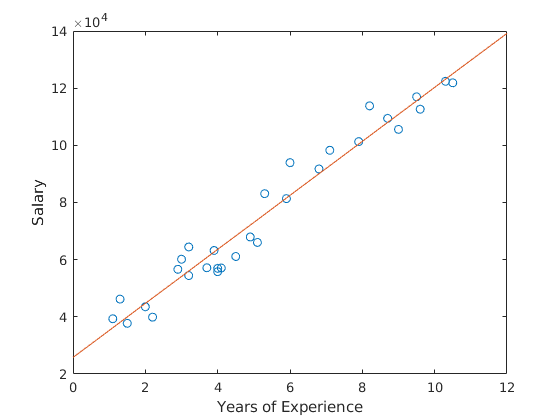

x=linspace(0,12,100)';
ypred=predict(mdl,x);
plot(data.YearsExperience,data.Salary,'o',x,ypred)
xlabel('Years of Experience')
ylabel('Salary')

## Hypothesis Testing

Sxx=sum((data.YearsExperience-mean(data.YearsExperience)).^2)

Sxx =    2.3355e+02


Syy=sum((data.Salary-mean(data.Salary)).^2)

Syy =    2.1795e+10


Sxy=sum((data.YearsExperience-mean(data.YearsExperience)).*(data.Salary-mean(data.Salary)))

Sxy =    2.2071e+06


r=Sxy/sqrt(Sxx*Syy)

r =    9.7824e-01


r^2

ans =    9.5696e-01


mdl.Rsquared

ans = struct with fields:
    Ordinary: 9.5696e-01
    Adjusted: 9.5542e-01


n=height(data)

n =     30


z=0.5*sqrt(n-3)*log((1+r)/(1-r))

z =    1.1717e+01


P=normcdf(z,'upper')

P =    5.2008e-32
